% Rocky_5_closed_loop_poles.m
%
% 1) Symbolically calculates closed loop transfer function of PI disturbannce
% rejection control system for Rocky. 
% No motor model (M =1). With motor model (1st order TF)
%
% 2) Specify location of (target)poles based on desired reponse. The number of
% poles = denominator polynomial of closed loop TF
%
% 3) Extract the closed loop denomiator poly and set = polynomial of target
% poles
%
% 4) Solve for Ki, Kp, Ji, Jp, Ci to match coefficients of polynomials. In general,
% this will be underdefined and will not be able to place poles in exact
% locations. In this case (5th order), the control constants can be found exactly 
%
% 5) Plot impulse response to see closed-loop behavior. 

clear all; 
close all;

syms s a b l g Kp Ki Jp Ji Ci   % define symbolic variables

Hvtheta = -s/l/(s^2-g/l);       % TF from velocity to angle of pendulum

K = Kp + Ki/s                  % TF of the PI angle controller
M = a*b/(s+a)                  % TF of motor (1st order model) 
J = Jp + Ji/s + Ci/s^2;         % TF of controller around motor-combined PI of x and v
Mfb = M/(1+M*J);                % Black's formula to get tf for motor with PI feedback control 

% closed loop transfer function from disturbance d(t)totheta(t)
% Hcloop = 1/(1-Hvtheta*M*K)    % use this for no motor feedback
% with motor feedback
Hcloop = 1/(1-Hvtheta*Mfb*K)    % use this for motor with feedback

pretty(simplify(Hcloop))       % to display the total transfer function

% Substitute parameters and solve
% system parameters
g = 9.81;
l = 0.362;  %effective length 
a = 1/17.48; %nominal motor parameters (tau)
b = 0.0031;  %nominal motor parameters (k) %both left motor

Hcloop_sub = subs(Hcloop) % sub parameter values into Hcloop

% specify locations of the target poles,
% choose # based on order of Htot denominator
% e.g., want some oscillations, want fast decay, etc. 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% POLES FOR INITIAL SYSTEM
p1 = -1 + 1*i   % dominant pole pair
p2 = -1 - 1*i    % dominant pole pair 
p3 = -2
p4 = -5   % dominant pole pair
p5 = -5 % dominant pole pair
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% POLES FOR STATIONARY SYSTEM
w_n = 0.877*6.28                        %natural frequency
angle1 = 20;                            %target angle1
angle2 = 20;                            %target angle2
p1 =  w_n*(-cosd(angle1) - sind(angle1))  % dominant pole pair
p2 = w_n*(-cosd(angle1) + sind(angle1))    % dominant pole pair 
p3 = -w_n
p4 = w_n*(-cosd(angle2) - sind(angle2))   % dominant pole pair
p5 = w_n*(-cosd(angle2) - sind(angle2)) % dominant pole pair 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% target characteristic polynomial
% if motor model (TF) is added, order of polynomial will increases
% tgt_char_poly = (s-p1)*(s-p2)*(s-p3)

% check polynomial-expand to fifth order 
tgt_char_poly = (s-p1)*(s-p2)*(s-p3)*(s-p4)*(s-p5)
exp_tgt_char_poly = expand(tgt_char_poly)

% get the denominator from Hcloop_sub
[n d] = numden(Hcloop_sub)

% find the coefficients of the denominator polynomial TF
coeffs_denom = coeffs(d, s)

% divide though the coefficient of the highest power term
coeffs_denom = coeffs(d, s)/(coeffs_denom(end))
% num_coeff_denom = length(coeffs_denom)

% find coefficients of the target charecteristic polynomial
coeffs_tgt = coeffs(tgt_char_poly, s)
% num_coeff_tgt = length(coeffs_tgt)

% for check. reorder the coefficients to match the denomimator polynomial
for ii = 1:length(coeffs_denom)
    reord_coeffs_tgt(ii) = coeffs_tgt(length(coeffs_tgt) + 1 - ii);
end
% check roots of target polynomial-should be same as selected poles
roots_target = vpa(roots(reord_coeffs_tgt),4)


% solve the system of equations setting the coefficients of the
% polynomial in the target to the actual polynomials
solutions = solve(coeffs_denom(1:5) == coeffs_tgt(1:5), Jp, Ji,  Kp, Ki, Ci);

% display the solutions as double precision numbers
Kp = double(solutions.Kp)
Ki = double(solutions.Ki)
Ji = double(solutions.Ji)
Jp = double(solutions.Jp)
Ci = double(solutions.Ci)

%write out denominator polynomial 
aaa = vpa(subs(coeffs_denom),4)

% reorder coefficients for the check polynomial 
for ii = 1:length(coeffs_denom)
    chk_coeffs_denom(ii) = coeffs_denom(length(coeffs_denom) + 1 - ii);
end

% check poles should be same as chosen input poles 
check_closed_loop_poles = vpa (roots(subs(chk_coeffs_denom)), 4)

% write out target polynomial 
% bbb = vpa( expand( (s-check_closed_loop_poles(1))*(s-check_closed_loop_poles(2)) ...
%     *(s-check_closed_loop_poles(3))*(s-check_closed_loop_poles(4)) ...
%     *(s-check_closed_loop_poles(5)) ) )

% Plot impulse and step responses of closed-loop system
    TFstring = char(subs(Hcloop));
    % Define 's' as transfer function variable
    s = tf('s');
    % Evaluate the expression
    eval(['TFH = ',TFstring]);
    figure (1)
    impulse(TFH);   %plot the impulse reponse
    figure(2)
    step(TFH)       %plot the step response

## Initial System Reponse-to-Disturbance Data

clear length

initial = [
0.06	0.01	0.36	0.34	0.00;
-0.03	0.04	-0.04	0.31	0.00;
-0.03	0.05	0.26	0.05	0.00;
-0.05	0.06	0.23	0.21	0.00;
-0.04	0.07	0.10	0.09	0.00;
-0.02	0.06	-0.12	0.21	0.00;
-0.01	0.08	0.19	0.04	0.00;
-0.02	0.10	0.32	0.30	0.00;
-0.04	0.14	0.58	0.43	0.00;
-0.07	0.19	0.57	0.61	0.00;
-0.10	0.24	0.48	0.43	0.00;
-0.13	0.28	0.26	0.28	0.00;
-0.15	0.31	0.14	0.13	0.00;
-0.15	0.32	0.23	0.21	0.00;
-0.14	0.32	-0.28	-0.32	0.00;
-0.11	0.30	-0.09	-0.23	0.00;
-0.07	-0.03	-0.57	-0.61	0.00;
0.04	-0.09	-0.79	-0.76	0.00;
0.18	-0.16	-0.77	-0.73	0.00;
0.38	-0.22	-0.05	-0.22	0.00;
0.50	-0.19	0.63	0.31	0.00;
0.67	0.03	0.63	0.62	0.00;
0.94	0.01	0.66	0.64	0.00;
1.30	0.01	0.66	0.64	0.00;
1.24	0.01	0.66	0.64	0.00;
1.33	0.01	0.66	0.64	0.00;
1.37	0.01	0.66	0.64	0.00;
1.30	0.01	0.66	0.64	0.00;
];

t = linspace(0, 2, 28);

### Initial System: Wheel Velocities

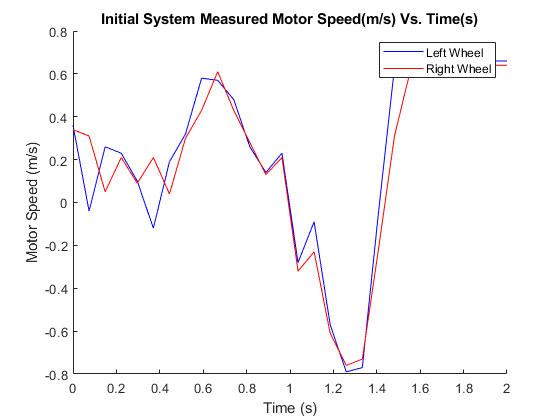

% Initial System Wheel Velocities

figure
clf
hold on

left_v = initial(:,3);
right_v = initial(:,4);

plot(t, left_v, 'b')
plot(t, right_v, 'r')
legend('Left Wheel', 'Right Wheel')
ylabel("Motor Speed (m/s)")
xlabel("Time (s)")
title("Initial System Measured Motor Speed(m/s) Vs. Time(s)")

### Initial System: Position of Cart

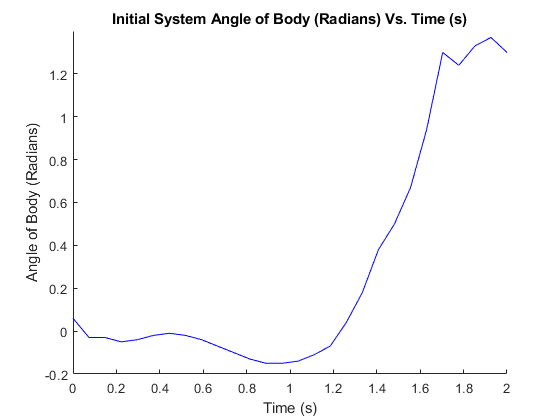

% Initial System Angle of Body

figure
clf
hold on

angle = initial(:,1);

plot(t, angle, 'b')
ylabel("Angle of Body (Radians)")
xlabel("Time (s)")
title("Initial System Angle of Body (Radians) Vs. Time (s)")

### Initial System: Position of Cart

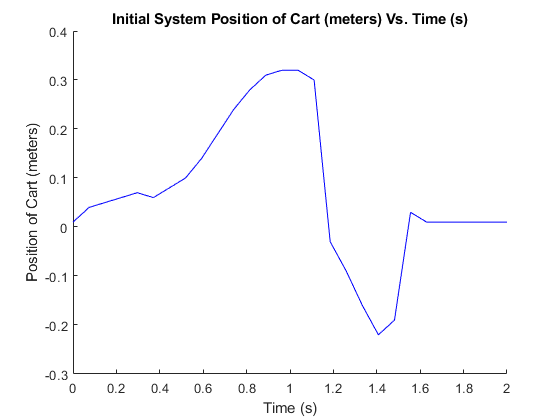

% Initial System Position of Cart

figure
clf
hold on

position = initial(:,2);

plot(t, position, 'b')
ylabel("Position of Cart (meters)")
xlabel("Time (s)")
title("Initial System Position of Cart (meters) Vs. Time (s)")

## Stationary Response-to-Disturbance Data

clear length

stationary = [
-0.04	0.12	-0.15	-0.08	0.00;
-0.04	0.12	-0.10	0.10	0.00;
-0.04	0.12	0.10	-0.10	0.00;
-0.03	0.11	-0.05	-0.21	0.00;
-0.02	0.10	0.10	0.01	0.00;
-0.01	0.09	-0.14	0.12	0.00;
-0.01	0.09	0.14	0.05	0.00;
-0.01	0.09	-0.17	-0.10	0.00;
-0.01	0.09	-0.09	0.12	0.00;
-0.00	0.09	0.08	0.00	0.00;
-0.01	0.09	0.23	0.03	0.00;
-0.01	0.10	0.06	0.21	0.00;
-0.02	0.11	0.08	0.15	0.00;
-0.04	0.13	-0.08	0.14	0.00;
-0.05	0.14	0.08	0.19	0.00;
-0.05	0.15	0.18	0.04	0.00;
-0.05	0.15	-0.06	-0.06	0.00;
-0.05	0.15	0.15	0.12	0.00;
-0.04	0.15	-0.14	-0.14	0.00;
-0.04	0.15	-0.12	-0.12	0.00;
-0.04	0.15	0.09	0.06	0.00;
-0.04	0.15	-0.10	-0.17	0.00;
-0.03	0.14	0.06	-0.12	0.00;
-0.03	0.14	-0.09	0.05	0.00;
-0.02	0.14	0.15	-0.17	0.00;
-0.02	0.14	-0.17	0.05	0.00;
-0.02	0.14	0.22	0.08	0.00;
-0.03	0.15	0.03	0.04	0.00;
-0.04	0.16	-0.10	0.04	0.00;
-0.05	0.17	-0.12	0.12	0.00;
-0.05	0.17	-0.06	0.01	0.00;
-0.05	0.18	0.14	0.13	0.00;
-0.05	0.18	-0.15	-0.14	0.00;
-0.05	0.17	-0.10	-0.10	0.00;
-0.05	0.18	0.10	0.08	0.00;
-0.04	0.17	-0.12	-0.09	0.00;
-0.03	0.17	0.08	-0.15	0.00;
-0.03	0.16	-0.17	-0.10	0.00;
-0.02	0.16	0.13	0.06	0.00;
-0.02	0.16	0.03	0.10	0.00;
-0.03	0.17	0.13	0.12	0.00;
-0.04	0.18	0.12	0.04	0.00;
-0.04	0.20	0.17	0.13	0.00;
-0.06	0.21	-0.09	0.05	0.00;
-0.06	0.22	0.10	0.04	0.00;
-0.07	0.23	0.10	-0.12	0.00;
-0.06	0.22	-0.17	-0.10	0.00;
-0.06	0.22	0.13	0.05	0.00;
-0.05	0.22	0.06	-0.15	0.00;
-0.05	0.23	0.23	0.09	0.00;
-0.05	0.23	-0.15	-0.09	0.00;
-0.05	0.24	0.14	0.03	0.00;
-0.05	0.24	0.19	0.03	0.00;
-0.06	0.25	-0.06	0.13	0.00;
-0.06	0.26	0.23	0.05	0.00;
-0.07	0.28	0.24	0.05	0.00;
-0.08	0.28	0.12	0.10	0.00;
-0.08	0.28	0.17	-0.12	0.00;
-0.07	0.29	0.08	-0.12	0.00;
-0.07	0.29	0.13	-0.08	0.00;
-0.07	0.29	-0.15	0.10	0.00;
-0.06	0.29	0.13	-0.14	0.00;
-0.05	0.29	0.08	0.17	0.00;
-0.06	0.30	0.12	0.10	0.00;
-0.07	0.31	-0.08	0.13	0.00;
-0.07	0.31	0.12	0.01	0.00;
-0.08	0.32	0.14	-0.08	0.00;
-0.08	0.32	-0.17	0.10	0.00;
-0.08	0.32	0.14	-0.14	0.00;
-0.08	0.32	0.08	-0.10	0.00;
-0.07	0.30	-0.24	-0.22	0.00;
-0.06	0.29	-0.06	-0.06	0.00;
-0.04	0.28	0.03	-0.15	0.00;
-0.04	0.28	-0.14	0.09	0.00;
-0.03	0.27	-0.10	0.05	0.00;
-0.04	0.28	0.12	0.12	0.00;
-0.05	0.29	0.24	0.12	0.00;
-0.07	0.30	0.23	0.12	0.00;
-0.08	0.31	-0.08	0.10	0.00;
-0.08	0.31	0.06	-0.09	0.00;
-0.09	0.31	-0.17	0.13	0.00;
-0.08	0.30	-0.22	-0.31	0.00;
-0.06	0.28	-0.10	-0.27	0.00;
-0.04	0.27	-0.12	-0.22	0.00;
-0.03	0.25	0.05	-0.21	0.00;
-0.02	0.24	-0.13	0.03	0.00;
-0.02	0.24	0.09	-0.12	0.00;
-0.02	0.24	0.01	0.05	0.00;
-0.04	0.25	-0.04	0.13	0.00;
-0.05	0.26	0.08	0.30	0.00;
-0.07	0.28	-0.05	0.12	0.00;
-0.08	0.28	0.12	0.15	0.00;
-0.08	0.28	-0.14	0.04	0.00;
-0.09	0.28	-0.24	-0.27	0.00;
-0.06	0.26	-0.26	-0.12	0.00;
-0.04	0.25	-0.15	-0.24	0.00;
-0.03	0.24	0.06	-0.13	0.00;
-0.03	0.23	0.08	-0.14	0.00;
-0.02	0.23	-0.14	0.13	0.00;
-0.02	0.23	0.05	0.01	0.00;
-0.04	0.25	0.26	0.06	0.00;
-0.06	0.26	-0.12	0.24	0.00;
-0.06	0.26	0.10	0.18	0.00;
-0.07	0.27	-0.06	-0.17	0.00;
-0.07	0.27	0.09	0.05	0.00;
-0.08	0.27	-0.14	-0.15	0.00;
-0.07	0.25	-0.15	-0.14	0.00;
-0.05	0.24	-0.19	-0.19	0.00;
-0.04	0.23	-0.21	-0.21	0.00;
-0.03	0.22	0.05	0.03	0.00;
-0.02	0.21	0.10	-0.17	0.00;
-0.02	0.21	-0.15	-0.01	0.00;
-0.02	0.21	0.23	0.12	0.00;
-0.03	0.23	0.23	0.26	0.00;
-0.05	0.24	0.26	0.05	0.00;
-0.07	0.25	-0.03	-0.04	0.00;
-0.07	0.26	0.12	0.03	0.00;
-0.08	0.26	-0.04	0.13	0.00;
-0.08	0.26	0.09	-0.15	0.00;
-0.07	0.26	-0.10	-0.03	0.00;
-0.06	0.25	-0.13	0.05	0.00;
-0.05	0.24	-0.05	-0.15	0.00;
-0.04	0.23	-0.09	0.03	0.00;
-0.03	0.23	-0.18	-0.15	0.00;
-0.03	0.22	0.13	-0.14	0.00;
-0.03	0.23	0.03	0.23	0.00;
-0.04	0.24	0.14	0.17	0.00;
-0.06	0.25	0.09	0.06	0.00;
-0.07	0.27	0.17	0.15	0.00;
-0.07	0.27	0.13	0.17	0.00;
-0.08	0.28	-0.08	-0.08	0.00;
-0.07	0.28	0.06	0.08	0.00;
-0.07	0.28	-0.15	-0.17	0.00;
-0.08	0.27	-0.05	-0.04	0.00;
-0.06	0.26	-0.12	-0.13	0.00;
-0.05	0.25	-0.18	-0.17	0.00;
-0.05	0.25	-0.18	0.08	0.00;
-0.03	0.24	0.13	-0.14	0.00;
-0.03	0.24	-0.10	0.06	0.00;
-0.03	0.25	0.19	0.04	0.00;
-0.05	0.26	0.15	0.23	0.00;
-0.06	0.27	0.19	0.26	0.00;
-0.07	0.28	0.21	0.03	0.00;
-0.08	0.29	-0.04	-0.13	0.00;
-0.08	0.29	0.15	0.13	0.00;
-0.08	0.30	-0.14	-0.08	0.00;
-0.07	0.29	-0.08	0.15	0.00;
-0.07	0.30	0.09	-0.13	0.00;
-0.07	0.30	-0.14	-0.09	0.00;
-0.06	0.30	0.14	0.08	0.00;
-0.06	0.30	0.09	-0.15	0.00;
-0.05	0.30	0.01	0.15	0.00;
-0.06	0.31	0.24	0.13	0.00;
-0.07	0.33	0.26	0.26	0.00;
-0.09	0.34	0.18	0.18	0.00;
-0.09	0.35	0.21	0.18	0.00;
-0.10	0.36	0.15	0.21	0.00;
-0.09	0.36	0.10	0.09	0.00;
-0.10	0.37	-0.04	0.10	0.00;
-0.09	0.37	0.14	-0.17	0.00;
-0.09	0.37	0.09	-0.09	0.00;
-0.09	0.37	-0.09	0.09	0.00;
-0.08	0.36	-0.17	0.09	0.00;
-0.08	0.36	-0.03	-0.15	0.00;
-0.07	0.35	-0.13	0.05	0.00;
-0.07	0.35	0.06	-0.23	0.00;
-0.06	0.34	0.09	0.04	0.00;
-0.06	0.34	-0.12	-0.08	0.00;
-0.06	0.33	0.08	0.06	0.00;
-0.06	0.33	-0.14	-0.15	0.00;
-0.05	0.33	0.14	0.15	0.00;
-0.07	0.34	-0.05	-0.04	0.00;
-0.06	0.34	0.17	0.04	0.00;
-0.08	0.35	-0.08	0.12	0.00;
-0.08	0.35	0.04	0.18	0.00;
-0.09	0.36	0.18	0.09	0.00;
-0.10	0.36	-0.14	-0.09	0.00;
-0.08	0.35	-0.09	-0.14	0.00;
-0.07	0.33	-0.13	-0.08	0.00;
-0.05	0.32	0.08	0.03	0.00;
-0.05	0.32	0.08	-0.17	0.00;
-0.05	0.32	0.10	0.12	0.00;
-0.05	0.32	0.08	0.10	0.00;
-0.05	0.31	-0.09	-0.08	0.00;
-0.05	0.32	0.09	0.03	0.00;
-0.07	0.33	0.15	-0.06	0.00;
-0.07	0.34	0.22	0.08	0.00;
-0.08	0.35	0.06	0.03	0.00;
-0.09	0.36	-0.04	-0.13	0.00;
-0.09	0.36	0.14	-0.09	0.00;
-0.09	0.36	-0.13	0.06	0.00;
-0.09	0.35	-0.05	-0.09	0.00;
-0.08	0.34	-0.08	-0.12	0.00;
-0.07	0.33	-0.12	0.01	0.00;
-0.06	0.33	0.09	-0.12	0.00;
-0.05	0.32	-0.15	0.05	0.00;
-0.05	0.33	0.19	0.17	0.00;
-0.06	0.34	0.23	0.19	0.00;
-0.07	0.35	0.26	0.17	0.00;
-0.09	0.37	0.18	0.15	0.00;
-0.10	0.37	0.22	0.05	0.00;
-0.10	0.38	-0.10	0.06	0.00;
-0.10	0.38	-0.09	-0.09	0.00;
-0.10	0.38	-0.03	0.10	0.00;
-0.09	0.37	-0.06	0.06	0.00;
-0.07	0.36	0.06	-0.06	0.00;
-0.07	0.35	-0.13	-0.10	0.00;
-0.06	0.35	0.05	-0.18	0.00;
-0.05	0.34	-0.09	0.13	0.00;
-0.05	0.35	0.09	0.01	0.00;
-0.06	0.37	0.19	0.27	0.00;
-0.08	0.38	0.30	0.39	0.00;
-0.10	0.40	0.12	0.31	0.00;
-0.11	0.41	-0.10	0.23	0.00;
-0.12	0.42	0.12	-0.13	0.00;
-0.12	0.42	0.15	0.05	0.00;
-0.11	0.41	-0.12	-0.04	0.00;
-0.09	0.40	-0.30	-0.08	0.00;
-0.08	0.39	0.03	-0.14	0.00;
-0.07	0.38	-0.12	-0.17	0.00;
-0.06	0.37	0.05	0.12	0.00;
-0.07	0.37	-0.17	-0.18	0.00;
-0.06	0.37	0.14	0.14	0.00;
-0.06	0.37	0.09	0.10	0.00;
-0.06	0.38	0.10	0.05	0.00;
-0.08	0.39	0.17	0.05	0.00;
-0.09	0.40	0.30	-0.08	0.00;
-0.10	0.41	0.03	0.21	0.00;
-0.11	0.42	0.12	-0.09	0.00;
-0.12	0.42	-0.08	-0.01	0.00;
-0.10	0.41	-0.14	-0.05	0.00;
-0.09	0.40	-0.13	-0.06	0.00;
-0.08	0.39	-0.17	0.05	0.00;
-0.07	0.38	0.04	0.05	0.00;
-0.06	0.37	0.09	0.08	0.00;
-0.06	0.36	-0.13	-0.14	0.00;
-0.06	0.36	-0.09	-0.09	0.00;
-0.07	0.37	0.12	0.12	0.00;
-0.07	0.36	-0.15	-0.15	0.00;
-0.06	0.36	-0.12	-0.10	0.00;
-0.07	0.36	0.08	0.01	0.00;
-0.08	0.37	0.17	0.14	0.00;
-0.08	0.37	-0.13	-0.13	0.00;
-0.08	0.37	-0.10	-0.10	0.00;
-0.08	0.37	0.08	0.06	0.00;
-0.09	0.36	-0.14	-0.15	0.00;
-0.08	0.36	0.05	-0.04	0.00;
-0.07	0.34	-0.23	-0.05	0.00;
-0.06	0.34	0.10	-0.13	0.00;
-0.06	0.32	-0.15	-0.21	0.00;
-0.06	0.32	-0.03	-0.12	0.00;
-0.05	0.31	0.08	-0.12	0.00;
-0.05	0.31	0.09	0.14	0.00;
-0.05	0.31	-0.09	-0.13	0.00;
-0.05	0.32	0.04	0.18	0.00;
-0.06	0.32	0.15	0.03	0.00;
-0.07	0.34	0.17	0.08	0.00;
-0.08	0.35	0.23	0.12	0.00;
-0.09	0.35	-0.06	0.12	0.00;
-0.09	0.36	0.10	0.01	0.00;
-0.09	0.36	-0.08	0.10	0.00;
-0.09	0.36	0.13	-0.14	0.00;
-0.09	0.36	-0.13	0.12	0.00;
-0.08	0.35	-0.24	-0.13	0.00;
-0.07	0.34	-0.05	-0.17	0.00;
-0.06	0.32	-0.26	-0.13	0.00;
-0.05	0.32	-0.12	0.04	0.00;
-0.05	0.31	-0.14	0.05	0.00;
-0.05	0.31	0.13	-0.14	0.00;
-0.05	0.31	-0.12	0.12	0.00;
-0.05	0.31	-0.09	0.08	0.00;
-0.05	0.31	0.10	-0.13	0.00;
-0.07	0.32	0.17	-0.12	0.00;
-0.07	0.32	0.09	-0.10	0.00;
-0.07	0.32	-0.09	0.06	0.00;
-0.07	0.32	0.14	-0.14	0.00;
-0.08	0.31	-0.08	-0.06	0.00;
-0.07	0.30	-0.06	-0.08	0.00;
-0.05	0.28	-0.10	-0.01	0.00;
-0.04	0.26	-0.06	-0.17	0.00;
-0.03	0.25	-0.13	0.03	0.00;
-0.03	0.24	-0.14	0.04	0.00;
-0.03	0.25	0.14	-0.14	0.00;
-0.03	0.25	-0.13	0.14	0.00;
-0.03	0.25	0.19	0.03	0.00;
-0.05	0.26	-0.04	0.05	0.00;
-0.06	0.27	-0.06	-0.08	0.00;
-0.06	0.27	0.13	0.08	0.00;
-0.07	0.27	-0.10	-0.06	0.00;
-0.07	0.27	-0.09	0.08	0.00;
-0.07	0.27	-0.21	-0.22	0.00;
-0.06	0.26	-0.22	-0.06	0.00;
-0.05	0.25	0.05	-0.12	0.00;
-0.04	0.24	0.10	-0.21	0.00;
-0.03	0.24	-0.12	0.04	0.00;
-0.03	0.24	-0.10	-0.01	0.00;
-0.04	0.24	0.08	0.01	0.00;
-0.05	0.25	-0.04	0.01	0.00;
-0.06	0.26	-0.06	-0.08	0.00;
-0.06	0.26	0.15	0.15	0.00;
-0.06	0.26	0.10	0.09	0.00;
-0.06	0.27	-0.08	-0.09	0.00;
-0.06	0.27	0.15	0.15	0.00;
-0.07	0.27	-0.10	-0.12	0.00;
-0.07	0.26	-0.22	-0.05	0.00;
-0.06	0.26	-0.05	-0.06	0.00;
-0.04	0.24	-0.18	0.08	0.00;
-0.04	0.24	-0.05	-0.18	0.00;
-0.03	0.23	-0.09	0.01	0.00;
-0.03	0.24	0.14	-0.15	0.00;
-0.03	0.24	-0.12	0.08	0.00;
-0.04	0.24	-0.08	-0.09	0.00;
-0.05	0.24	-0.03	0.19	0.00;
-0.06	0.25	-0.04	0.08	0.00;
-0.06	0.25	0.12	-0.09	0.00;
-0.06	0.25	-0.14	0.04	0.00;
-0.06	0.25	-0.08	-0.14	0.00;
-0.06	0.25	0.06	0.14	0.00;
-0.06	0.25	-0.13	0.08	0.00;
-0.06	0.24	-0.04	-0.12	0.00;
-0.05	0.24	-0.15	0.12	0.00;
-0.05	0.24	0.12	-0.12	0.00;
-0.04	0.24	0.08	-0.09	0.00;
-0.03	0.24	0.01	0.09	0.00;
-0.05	0.25	0.24	0.06	0.00;
-0.06	0.26	0.04	0.15	0.00;
-0.07	0.27	-0.04	0.15	0.00;
-0.07	0.28	0.08	0.00	0.00;
-0.08	0.29	0.14	0.12	0.00;
-0.08	0.29	0.09	-0.15	0.00;
-0.08	0.29	-0.08	0.12	0.00;
-0.07	0.28	-0.15	-0.14	0.00;
-0.06	0.27	-0.18	-0.18	0.00;
-0.04	0.26	-0.18	-0.18	0.00;
-0.04	0.25	-0.10	-0.10	0.00;
-0.03	0.25	0.09	0.05	0.00;
-0.03	0.26	0.05	0.14	0.00;
-0.04	0.27	0.23	0.13	0.00;
-0.06	0.29	0.23	0.28	0.00;
-0.08	0.31	0.10	0.18	0.00;
-0.10	0.32	-0.06	0.15	0.00;
-0.10	0.32	-0.08	-0.13	0.00;
-0.10	0.32	0.06	0.14	0.00;
-0.09	0.32	-0.10	-0.13	0.00;
-0.07	0.30	-0.21	-0.18	0.00;
-0.05	0.28	-0.26	-0.10	0.00;
-0.04	0.27	-0.21	-0.14	0.00;
-0.03	0.26	0.04	-0.15	0.00;
-0.02	0.26	-0.06	0.05	0.00;
-0.02	0.26	0.26	0.21	0.00;
-0.04	0.28	0.34	0.23	0.00;
-0.06	0.30	0.15	0.24	0.00;
-0.09	0.32	0.32	0.09	0.00;
-0.11	0.33	0.18	-0.01	0.00;
-0.10	0.34	0.09	0.14	0.00;
-0.11	0.33	-0.04	-0.23	0.00;
-0.08	0.32	-0.19	-0.26	0.00;
-0.07	0.30	-0.24	-0.24	0.00;
-0.05	0.28	-0.22	-0.08	0.00;
-0.04	0.27	-0.06	-0.17	0.00;
-0.03	0.26	-0.09	0.04	0.00;
-0.03	0.27	0.15	-0.14	0.00;
-0.03	0.27	0.19	0.05	0.00;
-0.05	0.29	0.23	0.17	0.00;
-0.06	0.30	0.17	0.32	0.00;
-0.08	0.32	0.17	0.31	0.00;
-0.09	0.33	0.15	0.12	0.00;
-0.09	0.33	-0.03	0.14	0.00;
-0.09	0.34	0.09	-0.08	0.00;
-0.08	0.34	-0.09	-0.01	0.00;
-0.08	0.34	0.15	0.12	0.00;
-0.08	0.34	-0.14	0.13	0.00;
-0.08	0.34	-0.09	0.05	0.00;
-0.08	0.34	0.08	-0.09	0.00;
-0.06	0.34	0.03	0.03	0.00;
-0.06	0.36	0.19	0.21	0.00;
-0.08	0.38	0.32	0.30	0.00;
-0.11	0.40	0.10	0.21	0.00;
-0.12	0.42	-0.03	0.19	0.00;
-0.13	0.43	0.10	-0.12	0.00;
-0.13	0.42	-0.04	-0.18	0.00;
-0.12	0.41	-0.34	-0.21	0.00;
-0.09	0.38	-0.21	-0.24	0.00;
-0.04	0.36	-0.24	-0.26	0.00;
-0.03	0.35	0.09	-0.12	0.00;
-0.02	0.36	0.27	0.10	0.00;
-0.06	0.39	0.21	0.17	0.00;
-0.09	0.42	0.36	0.44	0.00;
-0.13	0.45	0.23	0.41	0.00;
-0.15	0.47	-0.03	0.15	0.00;
-0.16	0.48	-0.08	-0.12	0.00;
-0.15	0.46	-0.39	-0.23	0.00;
-0.13	0.44	-0.39	-0.34	0.00;
-0.08	0.40	-0.40	-0.54	0.00;
-0.05	0.36	-0.55	-0.37	0.00;
-0.02	0.32	-0.34	-0.18	0.00;
-0.00	0.30	-0.31	0.00	0.00;
0.00	0.30	-0.12	-0.13	0.00;
-0.01	0.31	0.28	0.15	0.00;
-0.03	0.33	0.24	0.24	0.00;
-0.06	0.35	0.30	0.35	0.00;
-0.10	0.39	0.36	0.32	0.00;
-0.13	0.42	0.03	0.18	0.00;
-0.14	0.43	-0.03	-0.04	0.00;
-0.14	0.43	0.15	0.15	0.00;
-0.13	0.42	-0.23	-0.30	0.00;
-0.11	0.40	-0.40	-0.44	0.00;
-0.08	0.37	-0.30	-0.23	0.00;
-0.05	0.34	-0.35	-0.36	0.00;
-0.02	0.31	-0.01	-0.14	0.00;
-0.02	0.30	-0.14	-0.04	0.00;
-0.01	0.30	0.12	0.04	0.00;
-0.02	0.31	0.34	0.15	0.00;
-0.04	0.33	0.12	0.14	0.00;
-0.08	0.36	0.35	0.43	0.00;
-0.11	0.39	0.26	0.26	0.00;
-0.13	0.41	0.14	-0.04	0.00;
-0.13	0.41	-0.04	-0.08	0.00;
-0.13	0.41	-0.18	-0.13	0.00;
-0.11	0.39	-0.23	-0.36	0.00;
-0.09	0.37	-0.13	-0.27	0.00;
-0.06	0.34	-0.40	-0.32	0.00;
-0.03	0.31	-0.30	-0.27	0.00;
-0.02	0.30	-0.08	0.06	0.00;
-0.02	0.30	-0.14	-0.14	0.00;
-0.02	0.32	0.24	0.37	0.00;
];

t = linspace(0, 65, 426);

### Stationary System: Wheel Velocities

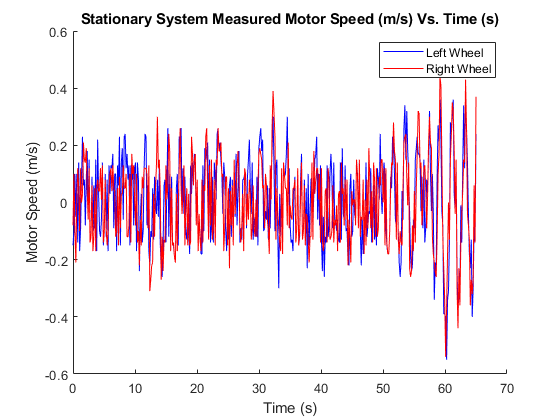

% Stationary System Wheel Velocities
figure
clf
hold on

left_v = stationary(:,3);
right_v = stationary(:,4);

plot(t, left_v, 'b')
plot(t, right_v, 'r')
legend('Left Wheel', 'Right Wheel')
ylabel("Motor Speed (m/s)")
xlabel("Time (s)")
title("Stationary System Measured Motor Speed (m/s) Vs. Time (s)")

### Stationary System: Angle of Body

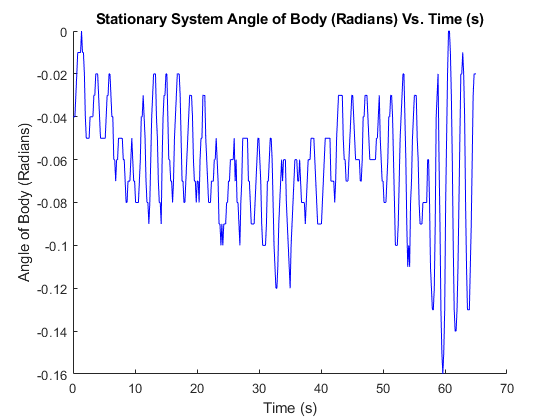

% Angle of Body

figure
clf
hold on

angle = stationary(:,1);

plot(t, angle, 'b')
ylabel("Angle of Body (Radians)")
xlabel("Time (s)")
title("Stationary System Angle of Body (Radians) Vs. Time (s)")

### Stationary System: Position of Cart

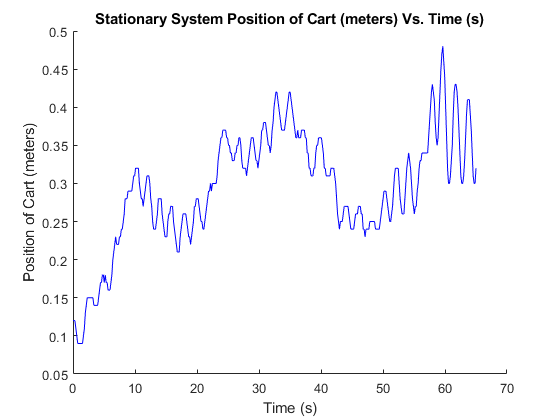

% Position of Cart

figure
clf
hold on

position = stationary(:,2);

plot(t, position, 'b')
ylabel("Position of Cart (meters)")
xlabel("Time (s)")
title("Stationary System Position of Cart (meters) Vs. Time")